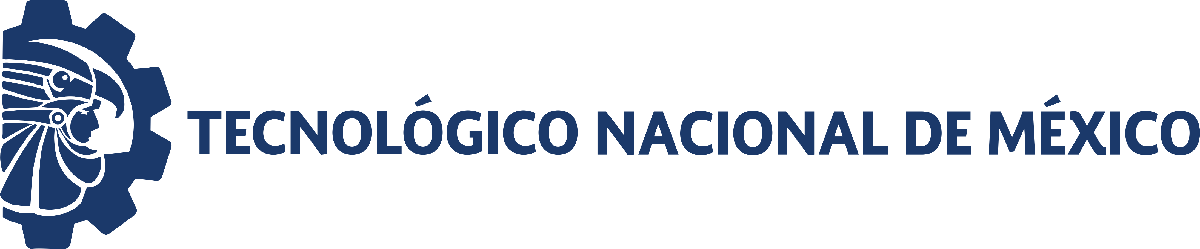                                 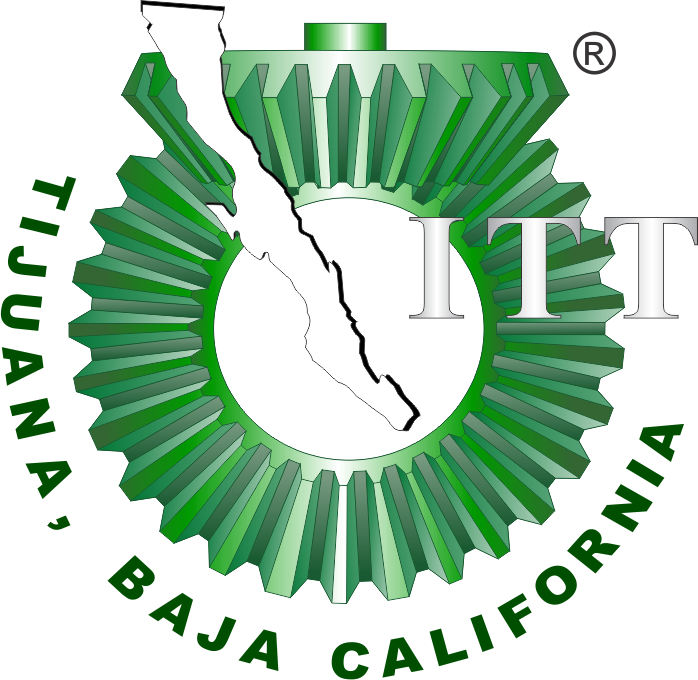

# Práctica 10: Sistema sanguineo

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

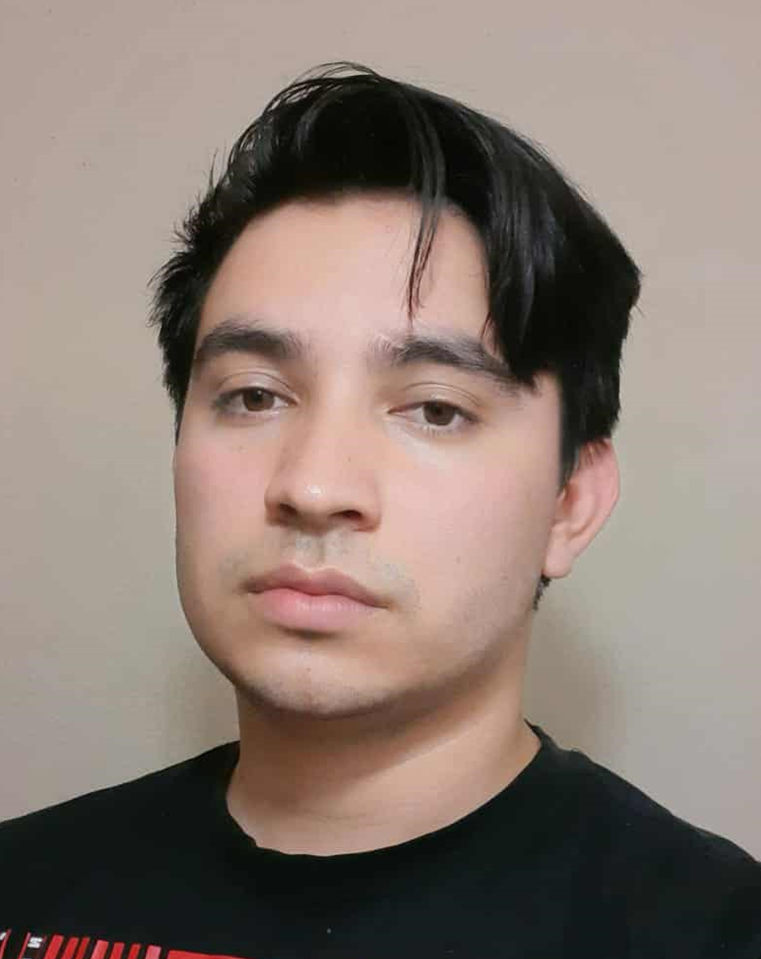

Nombre del alumno: **Erik Rasheed Rendón Carrillo **

Número de control: **20210818**

Correo institucional: **erik.rendonc201@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all'); format short
tend = 180; %Tiempo de simulacion es días
dt = 1E-3; %Intervalo de integración para el método de solución por diferencias finitas
n = round(tend/dt); %Cantidad de iteraciones para el método numérico

%Condiciones iniciales base para cada paciente
x1_0 = 59; x2_0 = 44; x3_0 = 885;

%Parametros particulares para cada paciente
gamma = [0.769;0.388;0.510;0.590;0.262;0.324;0.356;0.089;0.243;0.057];
beta = [1.650;0.867;1.617;2.615;1.518;2.676;0.891;2.557;0.925;0.879];


seed = 20210818; %Semilla para asegurar 
rng(seed,"twister")

%Intervalo de las condiciones iniciales
xmin = 0.99; xmax = 1.01;
interval = xmin +(xmax-xmin).*rand(numel(gamma),1);

%Condiciones iniciales para cada paciente
x1_0 = x1_0*interval; disp('x1(0) ='); disp(x1_0');

x1(0) =
   59.0668   58.5776   58.7357   59.3452   58.8728   59.5817   58.6822   59.3926   58.6229   59.2234



x2_0 = x2_0*interval; disp('x2(0) ='); disp(x2_0');

x2(0) =
   44.0498   43.6850   43.8029   44.2575   43.9051   44.4338   43.7630   44.2928   43.7187   44.1666



x3_0 = x3_0*interval; disp('x3(0) ='); disp(x3_0');

x3(0) =
  886.0016  878.6644  881.0359  890.1784  883.0915  893.7249  880.2325  890.8890  879.3430  888.3504



## **Caso: Sin transfusión sanguínea [u(t) = 0]**

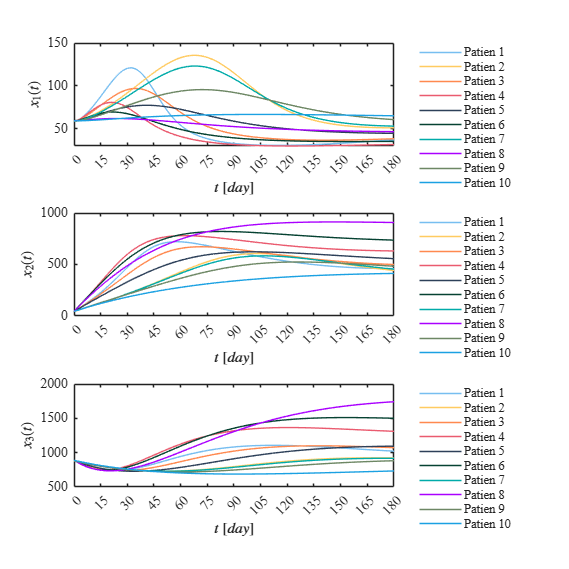

u = zeros(n+1,1); %No hay transfución
fig = 1; 
for i = 1:10
    [t,x1,x2,x3] = system(x1_0(i),x2_0(i),x3_0(i),beta(i),gamma(i),u,dt,tend);
    plotdata(t,x1,x2,x3,fig)
end

## **Caso: Transfusión sanguínea [u(t) = 1 [t1,t2]]**

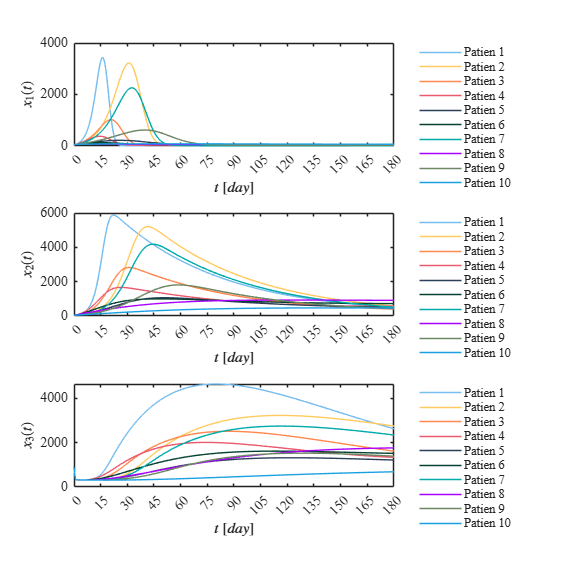

u2 = zeros(n+1,1); u2(1:1000) = 1; %Hay transfución 
fig = 2; 
for i = 1:10
    [t,x1,x2,x3] = system(x1_0(i),x2_0(i),x3_0(i),beta(i),gamma(i),u2,dt,tend);
    plotdata(t,x1,x2,x3,fig)
end

## **Función: Modelo matemático **


$$\dot{x_1 } =\beta \left(X_0 -k_1 x_1 \right)+\frac{\gamma \left(B_{\textrm{ase}} -x_3 \right)\left(1-u\left(t\right)\right)x_1 }{B_{\textrm{ase}} }$$



$$\dot{x_2 } =\beta \left(k_1 x_1 -k_2 x_2 \right)$$



$$\dot{x_3 } =\beta \left(k_2 x_2 -\alpha x_3 \right)-u\left(t\right)x_3$$


function[t,x1,x2,x3] = system(x1_0,x2_0,x3_0,beta,gamma,u,dt,tend)
    %parámetros fijos del sistema
    base = 885.42; X0 = 7.3785; k1 = 0.125; k2 = 0.01667; alpha = 0.00833;
    t = (0:dt:tend)';
    n = round(tend/dt);
    x1 = zeros(n+1,1); x1(1) = x1_0;
    x2 = zeros(n+1,1); x2(1) = x2_0;
    x3 = zeros(n+1,1); x3(1) = x3_0;

    for i=1:n %Método de Euler (diferencias finitas)
        x1(i+1) = x1(i) + (beta*(X0-k1*x1(i)) + gamma*(base - x3(i))*(1-u(i))*x1(i)/base)*dt;
        x2(i+1) = x2(i) + (beta*k1*x1(i) - k2*x2(i))*dt;
        x3(i+1) = x3(i) + (beta*(k2*x2(i) - alpha*x3(i)) - u(i)*x3(i))*dt;
    end

end

## **Función: Respuesta a las señales**

function plotdata(t,x1,x2,x3,fig)
    set(figure(fig),'Color','w')
    set(gcf,'Units','Centimeters','Position',[1,1,20,20])
    mycolors = [119,190,240;
                255,203,97;
                255,137,79;
                234,91,111;
                45,64,89;
                6,66,50;
                0,171,169;
                170,0,255;
                109,135,100;
                27,161,226]/255;

    subplot(3,1,1)
    hold on; grid off; box on;colororder(mycolors)
    plot(t,x1)
    xlabel('$t$ $[day]$','Interpreter','latex','FontSize',10)
    ylabel('$x_1(t)$','Interpreter','latex','FontSize',10)
    xlim([0 180]); xticks(0:15:180)
    L = legend('Patien 1','Patien 2','Patien 3','Patien 4','Patien 5', ...
        'Patien 6','Patien 7','Patien 8','Patien 9','Patien 10');
    set(L,'FontSize',9,'Box','Off','Location','NorthEastOutside');
    set(gca,'Fontname','Times New Roman','FontSize',10)

    subplot(3,1,2)
    hold on; grid off; box on;colororder(mycolors)
    plot(t,x2)
    xlabel('$t$ $[day]$','Interpreter','latex','FontSize',10)
    ylabel('$x_2(t)$','Interpreter','latex','FontSize',10)
    xlim([0 180]); xticks(0:15:180)
    L = legend('Patien 1','Patien 2','Patien 3','Patien 4','Patien 5', ...
        'Patien 6','Patien 7','Patien 8','Patien 9','Patien 10');
    set(L,'FontSize',9,'Box','Off','Location','NorthEastOutside');
    set(gca,'Fontname','Times New Roman','FontSize',10)
    
    subplot(3,1,3)
    hold on; grid off; box on;colororder(mycolors)
    plot(t,x3)
    xlabel('$t$ $[day]$','Interpreter','latex','FontSize',10)
    ylabel('$x_3(t)$','Interpreter','latex','FontSize',10)
    xlim([0 180]); xticks(0:15:180)
    L = legend('Patien 1','Patien 2','Patien 3','Patien 4','Patien 5', ...
        'Patien 6','Patien 7','Patien 8','Patien 9','Patien 10');
    set(L,'FontSize',9,'Box','Off','Location','NorthEastOutside');
    set(gca,'Fontname','Times New Roman','FontSize',10)

    if fig == 1
        exportgraphics(gcf,'Caso sin transfusion.pdf','ContentType','vector')
        exportgraphics(gcf,'Caso sin transfusion.png','ContentType','vector')
    elseif fig == 2
        exportgraphics(gcf,'Caso con transfusion.pdf','ContentType','vector')
        exportgraphics(gcf,'Caso con transfusion.png','ContentType','vector')
    end
end